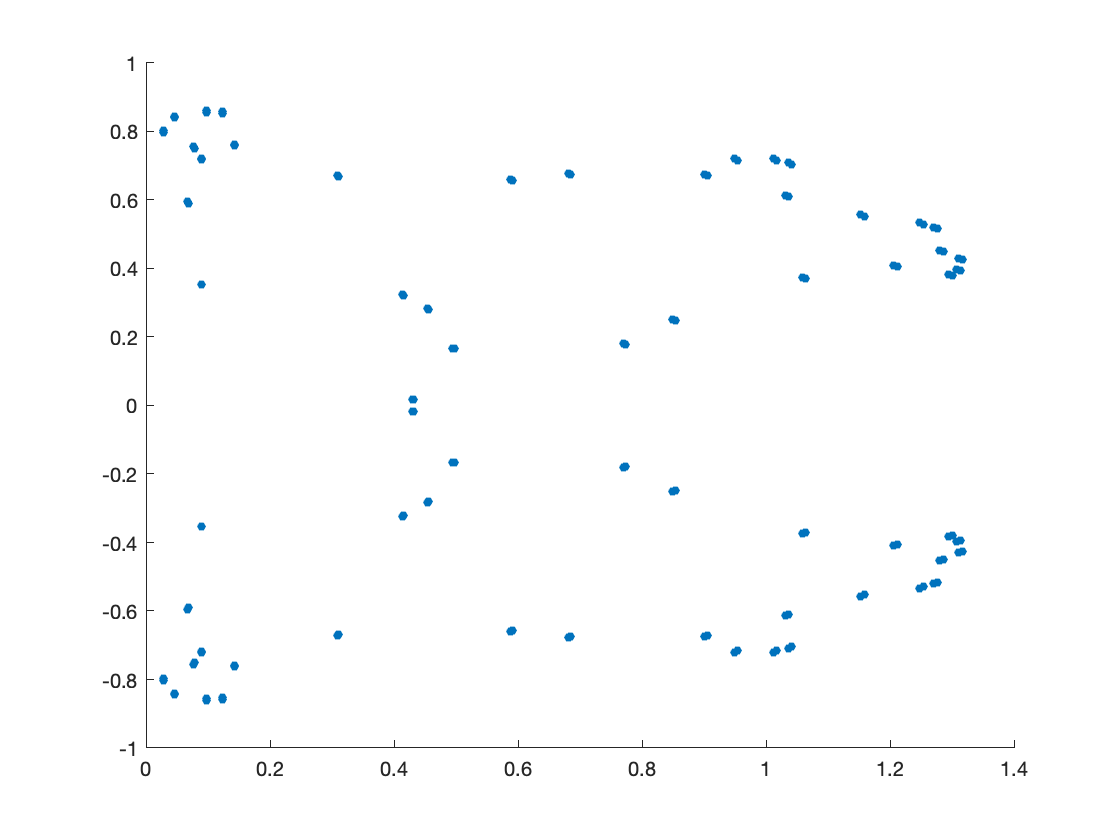

juliamodified2(-0.123 + 0.745i, 6, 200)

Plots the julia set for any given complex value for c at a greater level of detail than juliasimple.

function output = juliamodified2(c, depth, res)
    
    f = @(z, c) sqrt(z - c);
    points = [1];
    pointsSoFar = [];
    
    for j = 1:depth
        if j < 6
            val = f(points, c);
            points = [val -val];
        else
            [points, pointsSoFar] = reducedInvImage(points, pointsSoFar, c, res);
        end
    end
    
    pointsSoFar = [pointsSoFar points];
    scatter(real(pointsSoFar), imag(pointsSoFar), 20, 'filled')
end

function [newPoints, out_pointsSoFar] = reducedInvImage(points, pointsSoFar, c, res)
    newPoints = setdiff(invImage(points, c, res), pointsSoFar);
    out_pointsSoFar = union(newPoints, pointsSoFar)';
end

function output_points = invImage(input_points, c, res)
    L = sqrt(input_points - c);
    Lres = (res + res*1i)*ones(1, length(L));
    output_points = [(my_floor(Lres, L) ./ res) (my_floor(Lres, -L) ./ res)];
end

function output = my_floor(z1, z2)
    x = real(z2) .* floor(real(z1) / real(z2));
    y = imag(z2) .* floor(imag(z1) / imag(z2));
    
    if isnan(x)
        x = real(z1);
    elseif isnan(y)
        y = imag(z1);
    end
    
    output = x + y.*1i;
end
